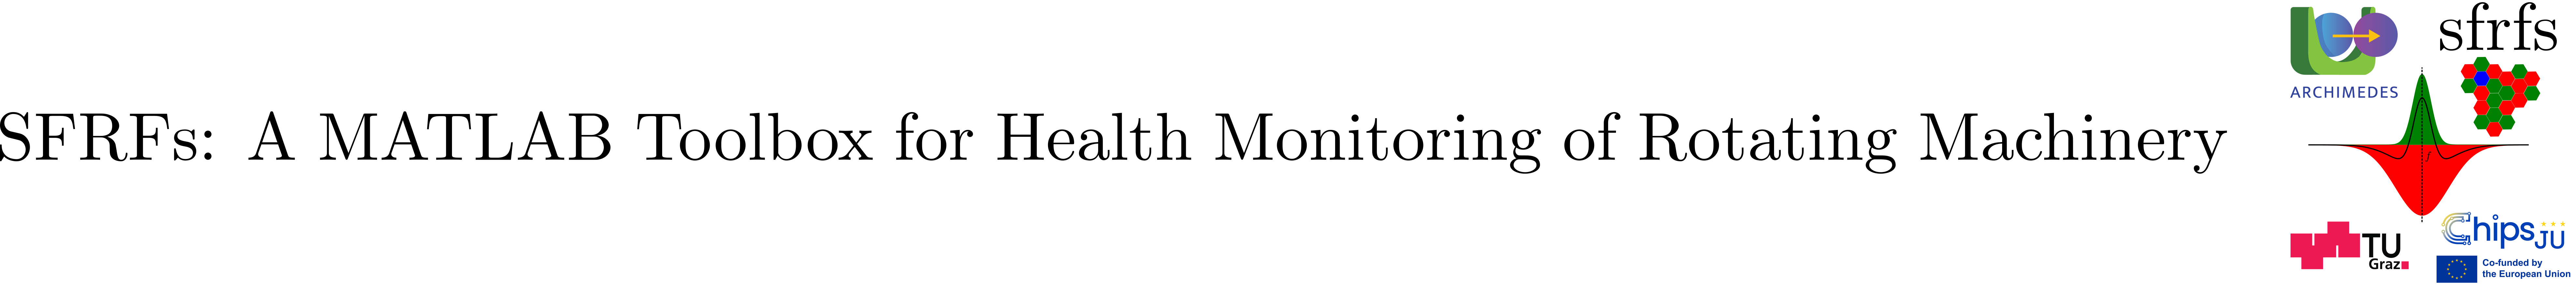

# FaultBandsTableSchema

## Summary

`FaultBandsTableSchema` extends `FaultConditionTableMetaSchema` with the column used to store fault-frequency band definitions.

## Description

Fault bands tables index fault-specific records at concrete operating conditions via the base key `(FaultGroup, Speed, Load)` and blend in the corresponding band definitions used for receptive-field construction.

The additional column `RECEPTIVEFIELDBANDS` stores, per row, a collection of band instances (typically `containers.Map` objects keyed by `dicts.BandMapSchema`).

### Defined columns

### Inherited columns

This schema inherits the base fault-condition columns from [`FaultConditionTableMetaSchema`](matlab:open('./FaultConditionTableMetaSchema.mlx')):

### Notes

- Base columns are inherited from `FaultConditionTableMetaSchema`.

- `RECEPTIVEFIELDBANDS` is typically produced by `FaultFrequencyBands.computeBands` and consumed by downstream perceptual components (RFGFs, fault-condition selection, extraction).

### See also

[`FaultFrequencyBands`](matlab:open('./FaultFrequencyBands.mlx')), [`FaultConditionTableMetaSchema`](matlab:open('./FaultConditionTableMetaSchema.mlx')), [`BandMapSchema`](matlab:open('./BandMapSchema.mlx')), [`FaultBandsExtractSchema`](matlab:open('./FaultBandsExtractSchema.mlx'))

## Example

% Example: attach fault-band definitions to a fault-condition table row

import tables.FaultConditionTableMetaSchema
import tables.FaultBandsTableSchema
import dicts.BandMapSchema
import structs.OpponentBandsSchema

ft = SFRFsParametersRollingBearings.OUTER_RACE_FAULT_TYPE_NAME;
fg = BearingFrequencyBands.faultTypeGroups(ft);
ds = BearingFrequencyBands.faultTypeDescriptions(ft);

b = struct();
b.(OpponentBandsSchema.CENTER) = [95, 105];
b.(OpponentBandsSchema.SURROUND) = [90, 110];

m = containers.Map('KeyType','char','ValueType','any');
m(BandMapSchema.BANDS) = b;
m(BandMapSchema.HARMONIC) = 1;
m(BandMapSchema.SIDEBAND) = 0;
m(BandMapSchema.LABEL) = "1" + string(BearingFrequencyBands.BPFO_CODE);


% set values
T = table();
T.(FaultBandsTableSchema.FAULTGROUP) = fg;
T.(FaultBandsTableSchema.SPEED) = 35;
T.(FaultBandsTableSchema.LOAD) = 12;
T.(FaultBandsTableSchema.DESCRIPTION) = ds;
T.(FaultBandsTableSchema.RECEPTIVEFIELDBANDS) = { {m} };

disp("Columns: " + strjoin(string(T.Properties.VariableNames), ", "));

Columns: FaultGroup, Speed, Load, Description, ReceptiveFieldBands


disp(T);

    FaultGroup    Speed    Load       Description        ReceptiveFieldBands
    __________    _____    ____    __________________    ___________________

        1          35       12     "Outer Race Fault"        {1×1 cell}     



## API documentation

### MATLAB help

help tables.FaultBandsTableSchema

 FaultBandsTableSchema  Schema for fault frequency bands tables.
 
  Extends FaultConditionTableSchema with columns specific to fault
  frequency band definitions.
 
  See also: FaultFrequencyBands, tables.FaultConditionTableMetaSchema

    Documentation for tables.FaultBandsTableSchema



## Source code

The source of the class can be found in [FaultBandsTableSchema](matlab:open('../../+tables/FaultBandsTableSchema.m')).

## How to cite this work

Muñoz Gutiérrez, Stan, & Wotawa, Franz (2025). SFRFs: A MATLAB Toolbox for Health Monitoring of Rotating Machinery. Zenodo. DOI: [10.5281/zenodo.17631784](http://10.0.20.161/zenodo.17631784).

## References

- [1] Stan Muñoz Gutiérrez and Franz Wotawa. Optimized Spectral Fault Receptive Fields for Diagnosis-Informed Prognosis. In 36th International Conference on Principles of Diagnosis and Resilient Systems (DX 2025). Open Access Series in Informatics (OASIcs), Volume 136, pp. 9:1-9:20, Schloss Dagstuhl – Leibniz-Zentrum für Informatik (2025) [DOI:10.4230/OASIcs.DX.2025.9](https://doi.org/10.4230/OASIcs.DX.2025.9).